x = 0.1:0.001:5;
a = 0.2;
b = 0.5;
u11 = (2*x).^-1+sqrt((2.*x).^-2-a*x.^-1);
u12 = (2*x).^-1-sqrt((2.*x).^-2-a*x.^-1);
u22 = sqrt(b*x.^-1);
u21 = -sqrt(b*x.^-1);
v1 = (x-a).*x.^-2;
v2 = b.*x.^-2;
eq =find(real(u11)-real(u22)==min(u11-u22));
x(eq)

ans = 1.0200

u11(eq)

ans = 0.7005

figure
hold on
plot(x,u11)

plot(x,u12)

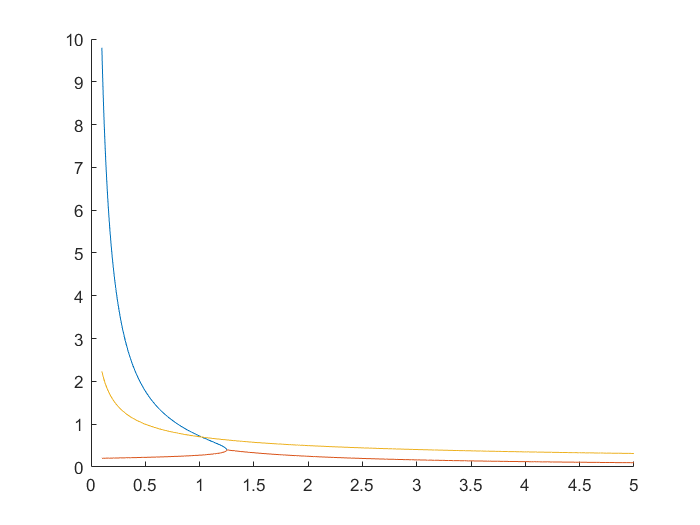

plot(x,u22)
hold off

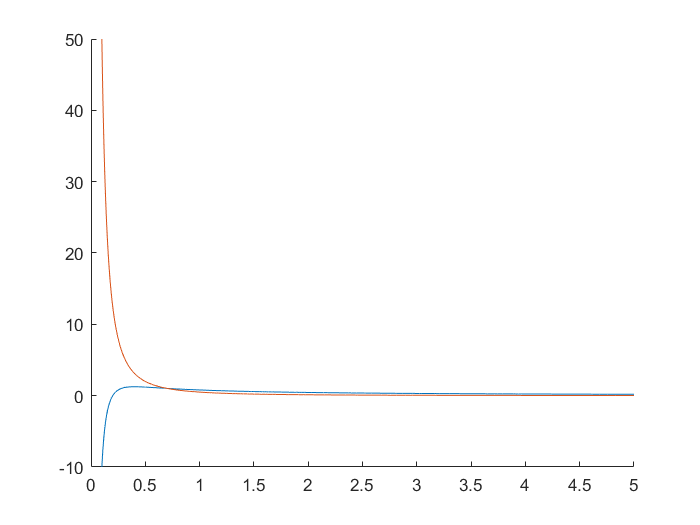

figure;
hold on
plot(x,v1)
plot(x,v2)
hold off